clear all
N = 5; n = 62;
a = 0.5; b = 2.5;
h = 0.045;
k = (b - a) / h + 1;

warning('off');

syms t x real

f(t, x) = (2 * N + 3) / (N + 2) * (n - 58) * ...
                sin( (3*N + 3) / ((2 * N + n - 58) * t) * x )

$$f(t, x) = \frac{52\,\sin\left(\frac{9\,x}{7\,t}\right)}{7}$$

u = zeros(1, k);
i = 1;
u(1, i) = N / 2;

for tau = a:h:b-h

    omega_1 = f(tau, u(1, i));
    omega_2 = f(tau + 1/2 * h, u(1, i) + 1/2 * h * omega_1);
    omega_3 = f(tau + 1/2 * h, u(1, i) + 1/2 * h * omega_2);
    omega_4 = f(tau + h, u(1, i) + h * omega_3);
    
    i = i + 1;
    u(1, i) = u(1, i - 1) + h/6 * (omega_1 + 2*omega_2 + 2 * omega_3 + omega_4);

end

% Практическое правило Рунге

h = h / 2;

u_1 = zeros(1, k);
i = 1;
u_1(1, i) = N / 2;

for tau = a:h:b-h

    omega_1 = f(tau, u_1(1, i));
    omega_2 = f(tau + 1/2 * h, u_1(1, i) + 1/2 * h * omega_1);
    omega_3 = f(tau + 1/2 * h, u_1(1, i) + 1/2 * h * omega_2);
    omega_4 = f(tau + h, u_1(1, i) + h * omega_3);
    
    i = i + 1;
    u_1(1, i) = u_1(1, i - 1) + h/6 * (omega_1 + 2*omega_2 + 2 * omega_3 + omega_4);

end

for i = fliplr([2:2:2*k-2])
    u_1(i) = [];
end

m = 4;
eps = max(transpose(abs(u - u_1))) / (2^(m-1) - 1)

eps = 4.2138e-05

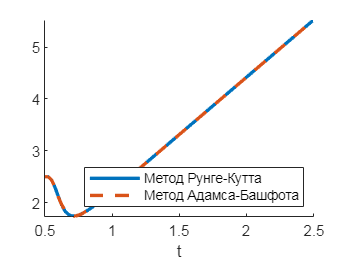


% Метод А-Б
h = h * 2;
u_2 = zeros(1, k);
u_2(1, 1) = u(1, 1);
u_2(1, 2) = u(1, 2);
u_2(1, 3) = u(1, 3);
u_2(1, 4) = u(1, 4);
i = 5;

for tau = a+4*h:h:b
    
    u_2(1, i) = u_2(1, i - 1) + ...
            h / 24 * (55 * f(tau - h, u_2(1, i - 1)) - ...
            59 * f(tau - 2*h, u_2(1, i - 2)) + ...
            37 * f(tau - 3*h, u_2(1, i - 3)) - ...
            9 * f(tau - 4*h, u_2(1, i - 4)));

    i = i + 1;
end

% Метод коррекции

u_3 = zeros(1, k);
u_3(1, 1) = u(1, 1);
u_3(1, 2) = u(1, 2);
u_3(1, 3) = u(1, 3);
u_3(1, 4) = u(1, 4);
i = 5;

for tau = a+4*h:h:b
    
    u_3(1, i) = u_3(1, i - 1) + h / 24 * (9 * f(tau, u_2(1, i)) + ...
                19 * f(tau - h, u_3(1, i - 1)) - ...
                5 * f(tau - 2*h, u_3(1, i - 2)) + ...
                f(tau - 3*h, u_3(1, i - 3)));

    i = i + 1;
end

% Решение задачи интерполяции
A = a:h:b;
syms tau

spl(1) = piecewise((tau >= A(1)) & (tau <= A(2)), -(tau - A(2)) / (A(2) - A(1)), 0);
for i = 2:k-1
    spl(i) = piecewise((tau >= A(i - 1)) & (tau <= A(i)), (tau - A(i - 1)) / (A(i) - A(i - 1)), ...
                       (tau >= A(i)) & (tau <= A(i + 1)), -(tau - A(i + 1)) / (A(i + 1) - A(i)), 0);
end
spl(k) = piecewise((tau >= A(k-1)) & (tau <= A(k)), (tau - A(k-1)) / (A(k) - A(k - 1)), 0);

u_rk(tau) = 0 * tau;
for i = 1:k
    u_rk(tau) = u_rk(tau) + spl(i) * u(i);
end

u_ab(tau) = 0 * tau;
for i = 1:k
    u_ab(tau) = u_ab(tau) + spl(i) * u_2(i);
end

u_pc(tau) = 0 * tau;
for i = 1:k
    u_pc(tau) = u_pc(tau) + spl(i) * u_3(i);
end

figure
fplot(u_rk(tau), [a, b], 'Linewidth', 2)
hold on
fp = fplot(u_ab(tau), [a, b], 'Linewidth', 2);
fp.LineStyle = '--';
legend("Метод Рунге-Кутта", "Метод Адамса-Башфота");
xlabel("t");
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
legend('Location', 'southeast')
box off
hold off

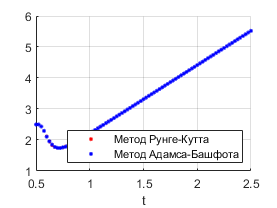


figure
plot(A, u, 'r.', 'MarkerSize',8, 'MarkerIndices',1:1:length(u));
hold on
plot(A, u_2, 'b.', 'MarkerSize',8, 'MarkerIndices',1:1:length(u));
legend("Метод Рунге-Кутта", "Метод Адамса-Башфота");
xlabel("t");
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
legend('Location', 'southeast')
box off
grid on
hold off

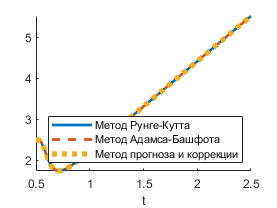


figure
fplot(u_rk(tau), [a, b], 'Linewidth', 2)
hold on
fp = fplot(u_ab(tau), [a, b], 'Linewidth', 2);
fp.LineStyle = '--';
fp = fplot(u_pc(tau), [a, b], 'Linewidth', 4);
fp.LineStyle = ':';
legend("Метод Рунге-Кутта", "Метод Адамса-Башфота", "Метод прогноза и коррекции");
xlabel("t");
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
legend('Location', 'southeast')
box off
hold off

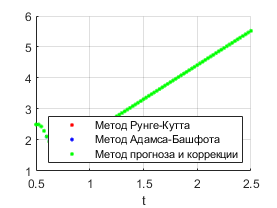


figure
plot(A, u, 'r.', 'MarkerSize',8, 'MarkerIndices',1:length(u));
hold on
plot(A, u_2, 'b.', 'MarkerSize',8, 'MarkerIndices',1:length(u_2));
plot(A, u_3, 'g.', 'MarkerSize',8, 'MarkerIndices',1:length(u_3));
legend("Метод Рунге-Кутта", "Метод Адамса-Башфота", "Метод прогноза и коррекции");
xlabel("t");
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
legend('Location', 'southeast')
box off
grid on
hold off